Here, we introduce a visual framework for identifying whether an arm composed of a set of actuators will be capable of producing the expected actuator force curves. We will first extract three keypoints along a trajectory where a robot arm is opening a drawer:

%% Step 1: Define target trajectory keybpoints
% Base pose: hanging down
pose_base = [0; 0; -pi/2];

% Keypoint poses: [x y theta]
pose_1 = [0.3; -0.4; 0];
pose_2 = [0.2; -0.4; 0];
pose_3 = [0.1; -0.4; 0];

poses = [pose_1 pose_2 pose_3];

% Create load vector
qx = 2; % Load of opening the drawer: 1N
Q = [qx; 0; 0]; % If we move to the left to open the drawer, then the drawer force will pull to the right

% Step 2: For each pose, find a shearless base-curve which reaches the goal point and minimizes certain desired metrics:
N_segs = 4;                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                         
%cost_func = @base_curve_cost_sum_of_std_from_each_segment;
cost_func = @base_curve_cost_sum_of_dists_from_target_squared;
cell_g_circ = find_base_curve_use_heuristics(pose_base, poses, Q, N_segs, cost_func);


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



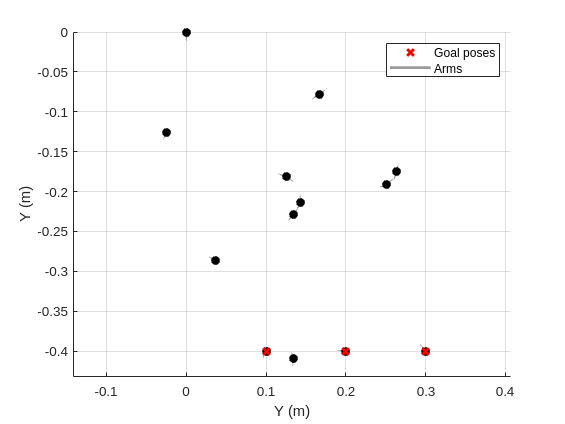


ax = axes(figure());
hold on
plot(poses(1, :), poses(2, :), 'rx', "MarkerSize", 7, "Linewidth", 2)
notch_points = zeros(3, size(poses, 2) * N_segs);

i_count = 1;
for i_pose = 1 : size(poses, 2)
    % For each tip pose, plot the arm that is reaching it
    pose_i = Pose2.hat(pose_base);
    mat_g_circ_out_i = cell_g_circ{i_pose};

    notch_points_i = zeros(3, N_segs + 1);
    for i = 1 : N_segs
        % For each segment along the way, save a notch-point denoting the
        % ends of the segment, as well as plot the rod for the segment itself
        rod_i = RodSegment(Pose2, 1, pose_i);
        rod_i.g_circ_right = mat_g_circ_out_i(:, i);
        Plotter2D.plot_rod(rod_i, ax);
    
        pose_i = pose_i * Twist2.expm(mat_g_circ_out_i(:, i));
        notch_points_i(:, i+1) = Pose2.vee(pose_i);
    end
    plot(notch_points_i(1, :), notch_points_i(2, :), 'ok', "markerfacecolor", "k");
end
plot(poses(1, :), poses(2, :), 'rx', "MarkerSize", 7, "Linewidth", 2)

legend(["Goal poses", "Arms"])

grid on
xlabel("Y (m)")
ylabel("Y (m)")

% Step 3: compute the moments that are induced at each segment for each target pose
test_rho = 0.05;    % Arbitrary design parameter - has no influence on the external reaction moment
test_l_0 = 1;       % Arbitrary design parameter - has no influence on the external reaction moment
test_arm = ArmSeriesFactory.constant_2d_muscle_arm(N_segs, test_rho, test_l_0);

cell_g_ucirc = {};
for i_target = 1 : size(poses)
    g_circ_right_i = cell_g_circ{i_target};
    cell_g_ucirc{i_target} = test_arm.calc_external_reaction(Q, g_circ_right_i);
end

profile ON

N_rhos = 20;
N_l_0s = 20;
rhos = linspace(0.04, 0.1, N_rhos);
l_0s = linspace(0.09, 0.17, N_l_0s);

n_each = 20;
n_frames = 4 * n_each;

p_max_muscle = 100;
p_max_bellow = 70;

p1 = [linspace(0, p_max_bellow, n_each), p_max_bellow * ones(1, n_each), linspace(p_max_bellow, 0, n_each), zeros(1, n_each)];
p2 = [zeros(1, n_each), linspace(0, p_max_muscle, n_each), p_max_muscle * ones(1, n_each), linspace(p_max_muscle, 0, n_each)];
p3 = [linspace(0, p_max_muscle, n_each), p_max_muscle * ones(1, n_each), linspace(p_max_muscle, 0, n_each), zeros(1, n_each)];
p4 = [zeros(1, n_each), linspace(0, p_max_bellow, n_each), p_max_bellow * ones(1, n_each), linspace(p_max_bellow, 0, n_each)];

ps = [p1; p2; p3; p4];

cell_rxns = cell(1, length(p1));
cell_rl = cell(1, length(p1));
cell_rgb = cell(1, length(p1));

N_poses = size(poses, 2);

tic
parfor i_p = 1 : n_frames
    p_i = ps(:, i_p);

    cell_rxns_i = cell(N_poses, N_segs);
    cell_rl_i = cell(N_poses, N_segs);
    cell_rgb_i = cell(N_poses, N_segs);

    i_plot = 1;
    for i_target = 1 : N_poses
        for i_seg = 1 : N_segs
            % Reaction area for this segmetn
            g_circ_right_i = cell_g_circ{i_target}(:, i_seg);
            g_ucirc_right_i = cell_g_ucirc{i_target}(:, i_seg);
            
            f_reaction = @(rho, l_0) f_reactions_4muscle(rho, l_0, g_circ_right_i, p_i);
            [~, mat_rxns, mat_rl, mat_rgb] = compute_reaction_image(f_reaction, rhos, l_0s);

            cell_rxns_i{i_target, i_seg} = mat_rxns;
            cell_rl_i{i_target, i_seg} = mat_rl;
            cell_rgb_i{i_target, i_seg} = mat_rgb;

            i_plot = i_plot+ 1;
        end 
    end

    cell_rxns{i_p} = cell_rxns_i;
    cell_rl{i_p} = cell_rl_i;
    cell_rgb{i_p} = cell_rgb_i;
end
cell_rxns_3d = cat(3, cell_rxns{:});
profile viewer

For each of the cells in the moment-image, we are interested in finding the arm design particles that can encircle target reaction. Let's start by doing this for one subplot. We will first find all the arm designs that encircle the target reaction using the matlab `inpolygon()` function. Then, we will plot the pre-image of these points in the design space, ie the regions in the design space which meet our design requirements for that segment.

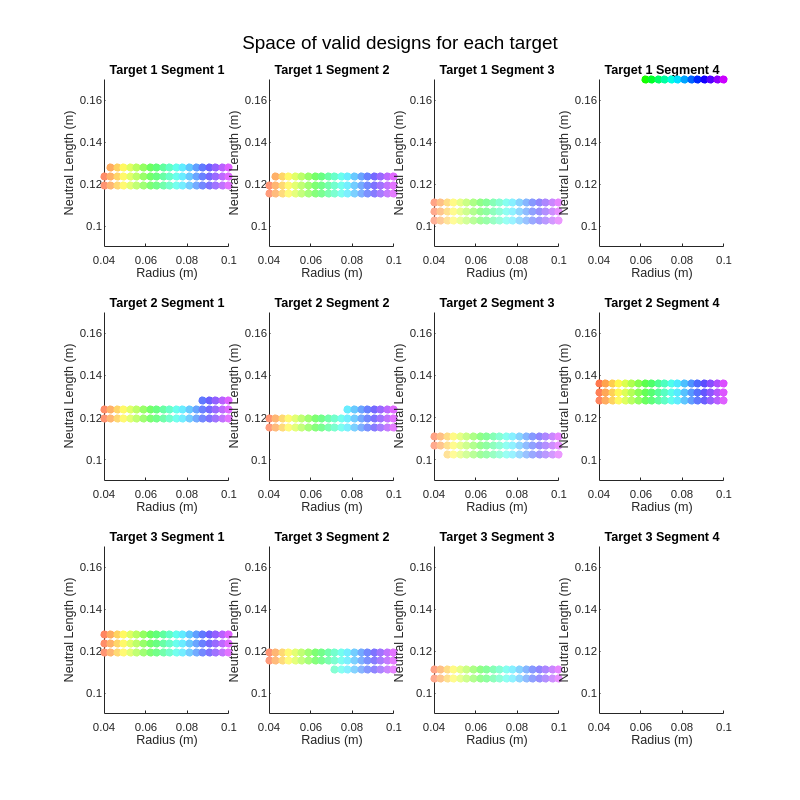

% Design parameter and color matrices should be shared across all segments
% and all pressures. This defines the design space.
mat_rl = cell_rl{1}{1, 1};
mat_rgb = cell_rgb{1}{1, 1};
radius_range = [min(mat_rl(1, :)), max(mat_rl(1, :))];
length_range = [min(mat_rl(2, :)), max(mat_rl(2, :))];

n_designs = 400; % TODO: Programmatically get this number
n_pressures = length(cell_rxns);

cell_designs_isvalid = cell(3, 3);
cell_polygons = cell(3,3);

for i_target = 1:3
    for j_segment = 1:4   
        mat_reactions_ij = cat(3, cell_rxns_3d{i_target, j_segment, :});
        ucirc_ij = cell_g_ucirc{i_target}(:, j_segment);
        
        designs_isvalid = false(n_designs, 1);
        polygons_i = zeros(2, n_pressures, n_designs);
        for i_design = 1 : n_designs
            % Get the reaction-space polygon associated with this design
            % [
            %   qf_p1, qf_p2, qf_p3, ..., qf_pm
            %   qm_p1, qm_p2, qm_p3, ..., qm_pm
            % ]
            % where each [qf_p1, qm_p1] comes from the design's column in the
            % pressure's associated reaction matrix. 
            
            % Fetch polygon points for design i
            Pi = mat_reactions_ij([1, 3], i_design, :);
            Pi = reshape(Pi, 2, n_pressures);
        
            designs_isvalid(i_design) = inpolygon(ucirc_ij(1), ucirc_ij(3), Pi(1, :), Pi(2, :));
            polygons_i(:, :, i_design) = Pi;
        end

        cell_designs_isvalid{i_target, j_segment} = designs_isvalid;
        cell_polygons{i_target, j_segment} = polygons_i;
    end
end

figure("Position", [0, 0, 800, 800])
sgtitle("Space of valid designs for each target")
for i_target = 1:3
    for j_segment = 1:4
        designs_isvalid_i = cell_designs_isvalid{i_target, j_segment};
        
        i_plot = 4*(i_target-1) + j_segment;
        subplot(3, 4, i_plot);
        scatter(mat_rl(1, designs_isvalid_i), mat_rl(2, designs_isvalid_i), [], mat_rgb(designs_isvalid_i, :), "filled");
        xlim(radius_range);
        ylim(length_range);
        xlabel("Radius (m)");
        ylabel("Neutral Length (m)")
        title(sprintf("Target %d Segment %d", i_target, j_segment));
    end
end

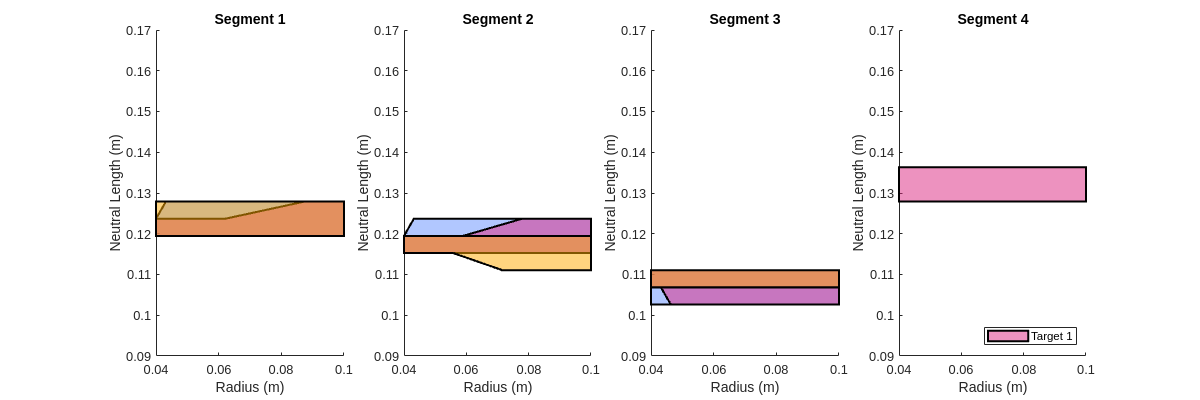

designs_isvalid_1 = cell_designs_isvalid{1, 1};
x = mat_rl(1, designs_isvalid_1)';
y = mat_rl(2, designs_isvalid_1)';
test_boundary = boundary(x, y);

% that are valid for all three target points
red = [220 38 127] / 255;
blue = [100, 143, 255] / 255;
yellow = [255 170 0] / 255;
green = [0 191 111] / 255;
black = [44 44 44] / 255;

colors = [blue; red; yellow; green];

figure("position", [0, 0, 1200, 400]);
for j_segment = 1:N_segs
    subplot(1, N_segs, j_segment);
    hold on

    for i_target = 1:3
        segment_j_design_isvalid = cell_designs_isvalid{i_target, j_segment};
        valid_rs = mat_rl(1, segment_j_design_isvalid)';
        valid_ls = mat_rl(2, segment_j_design_isvalid)';

        i_boundary = boundary(valid_rs, valid_ls);
        fill(valid_rs(i_boundary), valid_ls(i_boundary), colors(i_target, :), "FaceAlpha", 0.5, "Linewidth", 1.5);
    end

    %scatter(mat_rl(1, segment_j_design_isvalid), mat_rl(2, segment_j_design_isvalid), [], mat_rgb(segment_j_design_isvalid, :), "filled");
    xlim(radius_range);
    ylim(length_range);
    xlabel("Radius (m)");
    ylabel("Neutral Length (m)")
    title(sprintf("Segment %d", j_segment))
end
legend("Target 1", "Target 2", "Target 3", "location", "southeast")

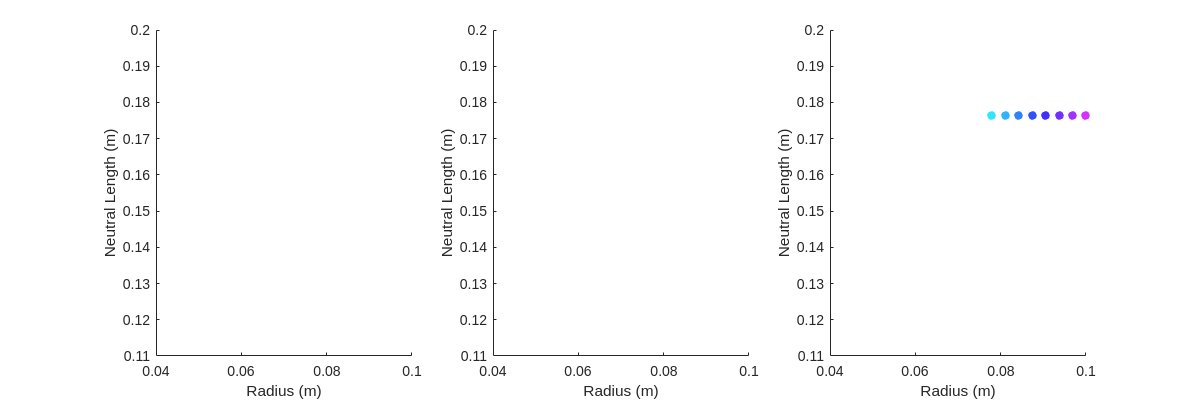

% Find the overlaps within the columns to find the set of segment designs
% that are valid for all three target points
figure("position", [0, 0, 1200, 400]);
for j_segment = 1:3
    segment_j_design_isvalid = ones(size(cell_designs_isvalid{1, 1}));
    for i_target = 1:3
        segment_j_design_isvalid = segment_j_design_isvalid & cell_designs_isvalid{i_target, j_segment};
    end
    subplot(1, 3, j_segment);
    scatter(mat_rl(1, segment_j_design_isvalid), mat_rl(2, segment_j_design_isvalid), [], mat_rgb(segment_j_design_isvalid, :), "filled");
    xlim(radius_range);
    ylim(length_range);
    xlabel("Radius (m)");
    ylabel("Neutral Length (m)")
end

Let's consider some of the polygons in the reaction-space:

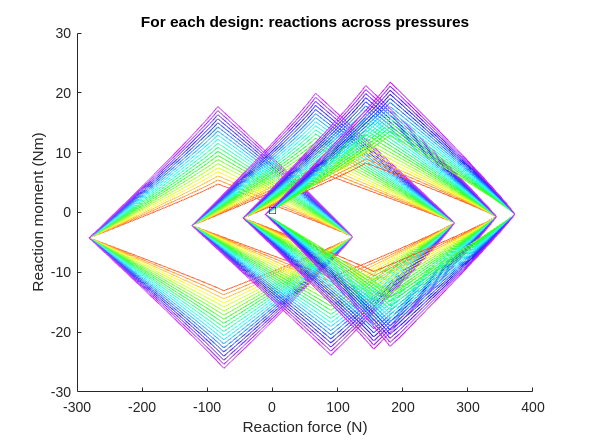

figure()
i_target = 1;
i_segment = 1;

designs_isvalid = cell_designs_isvalid{i_target, i_segment};
P_isvalid = cell_polygons{i_target, i_segment}(:, :, designs_isvalid);
rgb_isvalid = mat_rgb(designs_isvalid, :);

g_ucirc = cell_g_ucirc{i_target}(:, i_segment);

figure()
hold on;
for i = 1 : size(P_isvalid, 3)
    P_i = P_isvalid(:, :, i);
    plot(P_i(1, :), P_i(2, :), "color", rgb_isvalid(i, :));
end
plot(g_ucirc(1), g_ucirc(3), 'ksquare');
xlabel("Reaction force (N)")
ylabel("Reaction moment (Nm)")
title("For each design: reactions across pressures")

% Different cost functions 

function v_cost = base_curve_cost_v(v_in)
    % Formulate cost term as the variance of the lengths
    mat_g_circ_right  = v_geom_to_g_circ(v_in);

    lengths = mat_g_circ_right(1, :);
    v_cost = std(lengths);
end

% Kinematic base curve costs
function cost = base_curve_cost_sum_of_var_from_each_arm(mat_geom)
    % Note: This seems to reproduce the results of individually
    % minimizing each arm
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    v_stds = zeros(length(cell_g_circ_right), 1);
    
    for i = 1 : length(cell_g_circ_right)
        lengths_i = cell_g_circ_right{i}(1, :);
        v_stds(i) = std(lengths_i);
    end
    cost = sum(v_stds);
end

function cost = base_curve_cost_sum_of_std_from_each_segment(mat_geom)
    % Note: This seems to reproduce the results of individually
    % minimizing each arm
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    v_stds = zeros(length(cell_g_circ_right), 1);
    
    mat_g_circ_right = cat(3, cell_g_circ_right{:});

    for i = 1 : length(cell_g_circ_right)
        v_stds(i) = std(mat_g_circ_right(1, i, :));
    end
    cost = sum(v_stds);
end

function cost = base_curve_cost_sum_of_dists_from_target_squared(mat_geom)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    all_twists = [cell_g_circ_right{:}];
    all_ls = all_twists(1, :);

    target_l = 0.17;
    dist_from_target_l = all_ls - 0.17;
    cost = sum(100 * dist_from_target_l.^4);
end

function cost = base_curve_cost_norm_of_stds(mat_geom)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    v_cost = zeros(length(cell_g_circ_right), 1);
    
    for i = 1 : length(cell_g_circ_right)
        lengths_i = cell_g_circ_right{i}(1, :);
        v_cost(i) = std(lengths_i);
    end

    cost = norm(v_cost);
end

function cost = base_curve_cost_std_of_all_ls(mat_geom)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    all_twists = [cell_g_circ_right{:}];
    all_ls = all_twists(1, :);

    cost = std(all_ls);
end

function cost = base_curve_cost_std_dist_from_target_l(mat_geom)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    all_twists = [cell_g_circ_right{:}];
    all_ls = all_twists(1, :);

    target_l = 0.17;
    dist_from_target_l = abs(all_ls - 0.17);
    cost = norm(dist_from_target_l);
end

% Mechanics-based base-curve costs
function cost = base_curve_cost_min_shear_force(mat_geom)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    
    cell_g_ucirc_left = cell(size(cell_g_circ_right));
    for i = 1 : length(cell_g_circ_right)
        simple_arm.g_circ_right = cell_g_circ_right{i};
        cell_g_ucirc_left{i} = simple_arm.calc_external_reaction(tip_load);
    end
    all_g_ucircs = [cell_g_ucirc_left{:}];
    all_shears = all_g_ucircs(2, :);
    cost = norm(all_shears);
end

function cost = base_curve_cost_min_bending_moment(mat_geom)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    
    cell_g_ucirc_left = cell(size(cell_g_circ_right));
    for i = 1 : length(cell_g_circ_right)
        simple_arm.g_circ_right = cell_g_circ_right{i};
        cell_g_ucirc_left{i} = simple_arm.calc_external_reaction(tip_load);
    end
    all_g_ucircs = [cell_g_ucirc_left{:}];
    all_moments = all_g_ucircs(3, :);
    cost = norm(all_moments);
end

function mat_g_circ_right = v_geom_to_g_circ(v_geom)
    % Convert a "geometry vector" to a matrix of twists
    % By "geometry vector" I mean [l_1; k_1; l_2; k_2; ...; l_n; k_n]
    n_g_circ = length(v_geom)/2;
    mat_l_k = reshape(v_geom, [2, n_g_circ]);
    lengths = mat_l_k(1, :);        % lengths
    shears = zeros(1, n_g_circ);    % shears
    curvatures = mat_l_k(2, :);     % curvatures

    mat_g_circ_right = [lengths; shears; curvatures];
end

function cell_g_circ_out = mat_geom_to_g_circ(mat_geom)
    % Convert a "geometry matrix" to a cell array of matrices of twists
    
    N_poses = size(mat_geom, 2);
    N_segs = size(mat_geom, 1) / 2;
    cell_g_circ_out = cell(1, N_poses);
    for i = 1 : N_poses
        v_geom_i = mat_geom(:, i);
        cell_g_circ_out{i} = v_geom_to_g_circ(v_geom_i);
    end
end